close all, clear all, clc

The dimensions are assumed to be in mm.

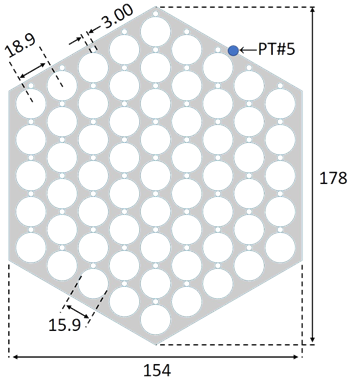 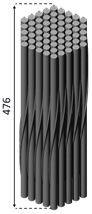

### Voume, whole Domain

Let's find the side of the hexagon. This can be elaborated as follows:

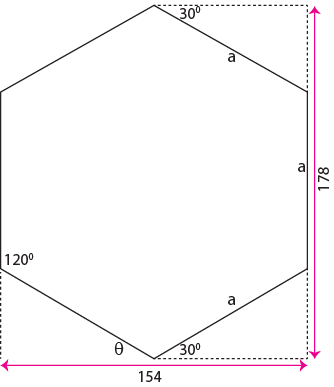

tht = 30;           % outer angle of hexagon
tht = deg2rad(tht);
L = 0.178;            % Length of the hexagonal bundle; m 

As, $2*a\;\sin \left(\theta \right)+a=L$

This renders,

a = L/2            % side of hexagon; m

a = 0.0890

Now, let's verify whether the calculation is ok. The width of the bundle is-

W = 2*a*cos(tht)    % width of bundle; m

W = 0.1542

% W = vpa(W)

Which is 154.12 mm, matching the 

Now, let's find the area of the hexagon, which is tthe basal area of the bundle


$$A=\frac{3\sqrt{\;3}}{2}a^2$$


A = 3*sqrt(3)/2 *a^2       % area of hexagon; m^2

A = 0.0206

So, volume of the hexagon

H = 0.476;      % height of bundle; m

Now, let's find the volume

V = A*H         % volume of full domain, m^3;

V = 0.0098

### Volume, Fuel Bundles

n_p = 61;           % total no. of pins
d_p = 0.0159;       % dia of pin; m^2
A_p = pi*d_p^2 /4;  % pin area; m^2
A_pT = A_p *n_p     % total pin CS area; m^2

A_pT = 0.0121

So, let's find the total volume of the pins 

V_pT = H *A_pT      % m^3

V_pT = 0.0058

### **Volume, Helical Wire**

Let's find the total basal area of the wire. 

n_w = 61;           % totoal no. of wires
d_w = 0.003;        % dia of wire; m^2
A_w = pi*d_w^2 /4;
A_wT = A_w *n_w     % total wire CS area; m^2

A_wT = 4.3118e-04

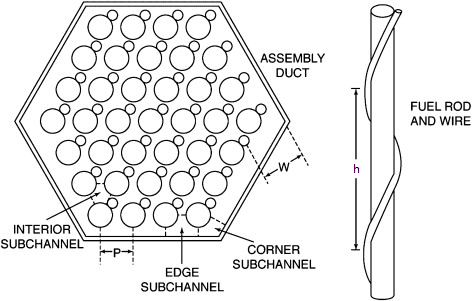

The above picture is self explanatory as the wire wraps the fuel pin with two turns around it. In our case, let the wire wraps the fuel pin with 1 turn. 

Now, let's find the volume of the wire.

nt = 1;             % no. of tursn of helix 

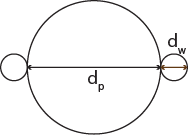

d_x = d_p + d_w;    % helix dia; m
c_x = pi*d_x;       % circumferance of helix; m
h_x = H/nt;         % rise of helix in one turn
l_x = sqrt(c_x^2 +h_x^2);   % helical length in one turn, m
L_x = nt *l_x      % total helix length

L_x = 0.4797

Then, the total volume of the helical wires would be-

V_wT =  L_x *A_wT

V_wT = 2.0683e-04

### **Other Volumes and Areas**

#### Solid's volume

V_s = V_wT + V_pT       % volume of the solid materials; m^3

V_s = 0.0060

#### Flow Volume

The volume of the fluid would be-

V_f = V - V_s           % volume of the flowing fluid; m^3

V_f = 0.0038

#### Volumetric ratio

$R_{\textrm{vf}} =\frac{V_f \;}{V}$;  here, $V_f =$ fluid volume; V = total volume of domain

R_Vf = V_f /V           % fluid's vol' ratio; #

R_Vf = 0.3903

R_Vs = 1 - R_Vf         % solid's vol' ratio; porosity; #

R_Vs = 0.6097

### Flow Area

Total solid CS Area

A_s = A_wT + A_pT;

And, total flow area of the fluid-

A_f = A - A_s         % flow area of fluid; m^2

A_f = 0.0080

This area would  be needed during Reynolds Number calculation

#### Hydraulic Diameter

p_cr = n_p *pi*(d_w + d_p);    % wetted perimeter, pins & wires; m
p_wl = 6*a;                 % wetted perimeter, wall; m
p_wt = p_cr + p_wl          % wetted perimeter, total; m

p_wt = 4.1559

So, hydraulic diameter would be

d_h = 4*A_f /p_wt           % hydraulic diameter; m

d_h = 0.0077